clc
clear

ObservationInfo = rlNumericSpec([3 1]);
ObservationInfo.Name = 'Beamforming States';
ObservationInfo.Description = 'beamRowFrac, beamColFrac','targetRangeIndex';

ObservationInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "Beamforming States"
    Description: "beamRowFrac, beamColFrac"
      Dimension: [3 1]
       DataType: "double"



ActionInfo = rlFiniteSetSpec((-2:0.1:2));
ActionInfo.Name = 'Beamforming Action';
AverageReward = 0

AverageReward = 0

datalog = [AverageReward 0 0 0];
StepHandle = @(Action,LoggedSignals) RadarEnvSame(Action,LoggedSignals,AverageReward,datalog);
ResetHandle = @() myResetFunction();

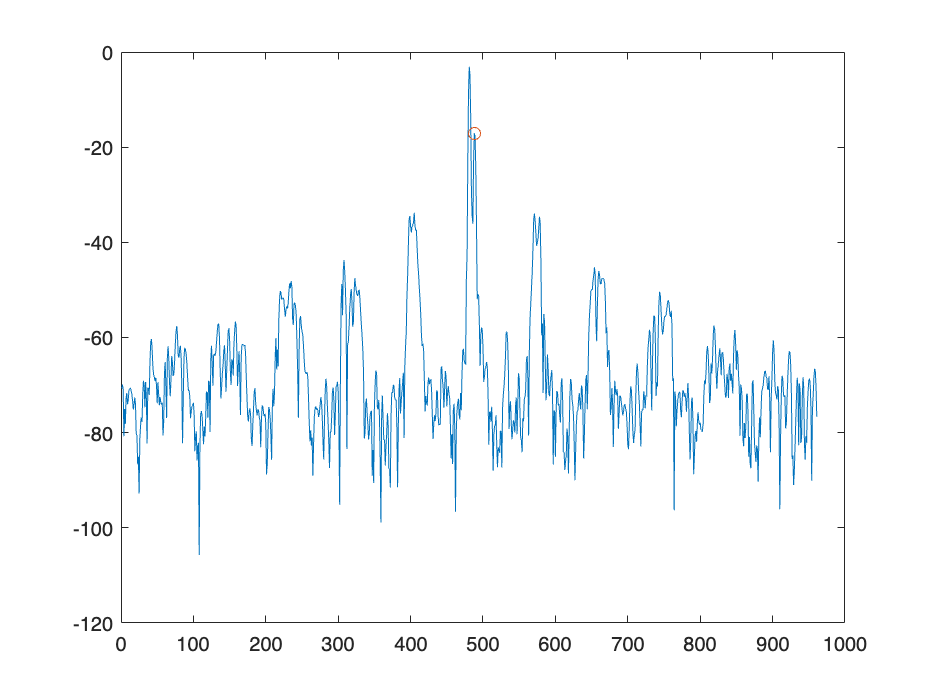

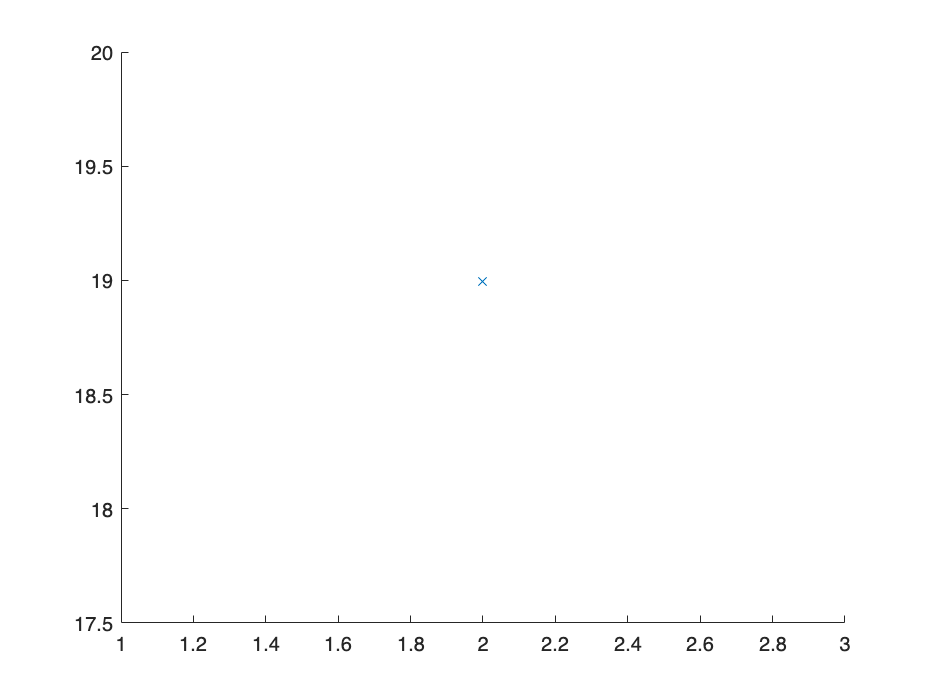

env = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandle,ResetHandle);

rng(0);
InitialObs = reset(env)

InitialObs =     0.7672
    0.9219
    0.6154


ActionInfo

ActionInfo =   rlFiniteSetSpec with properties:

       Elements: [41×1 double]
           Name: "Beamforming Action"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


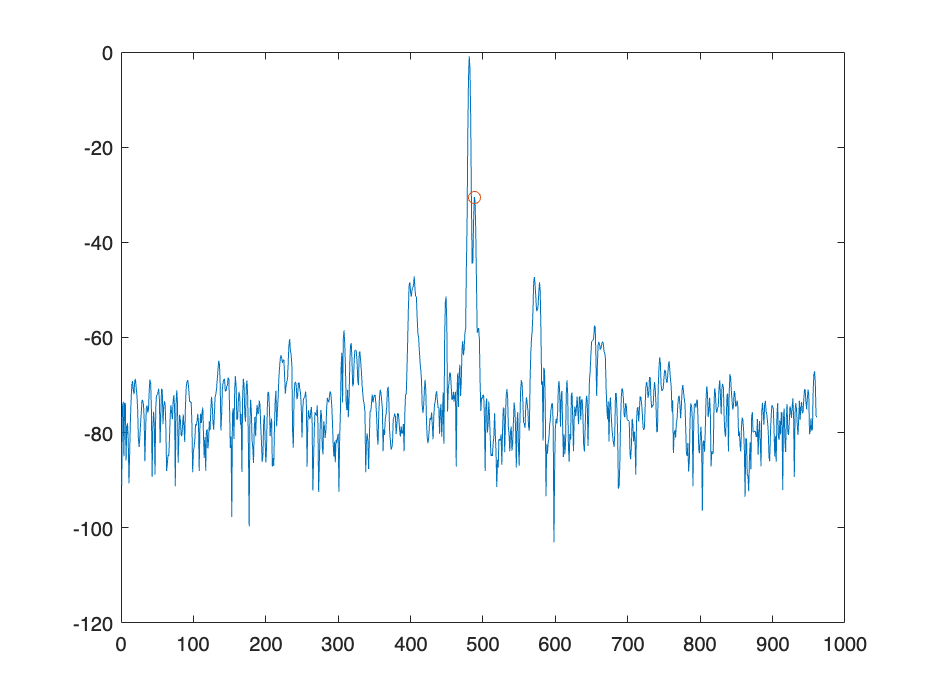

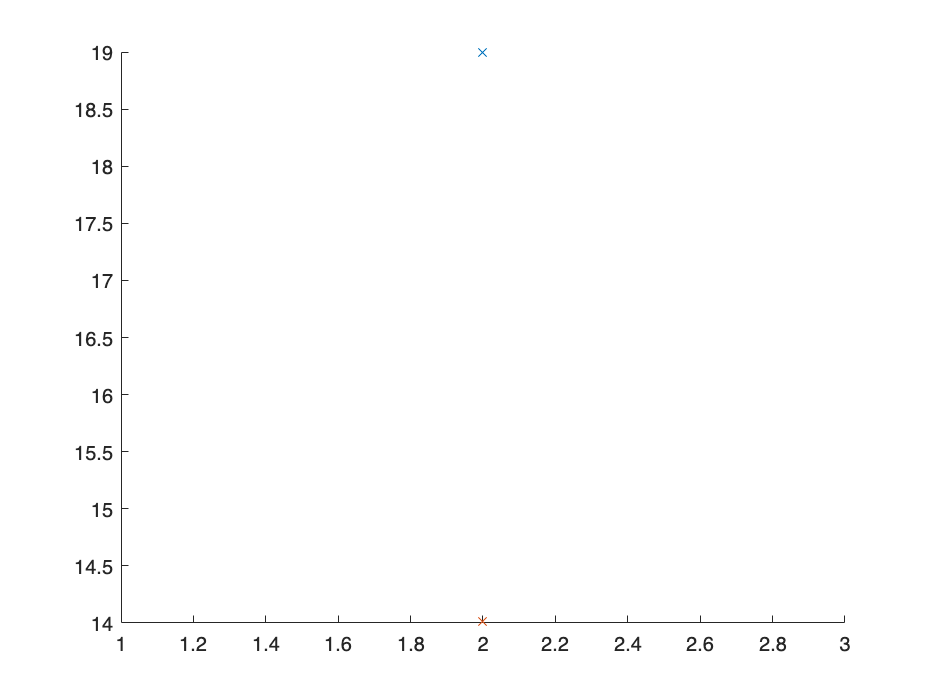

[NextObs,Reward,IsDone,LoggedSignals] = step(env,10);

NextObs

NextObs =     0.7683
    0.9207
    0.6154


dnn = [
    featureInputLayer(3,'Normalization','none','Name','state')
    fullyConnectedLayer(16,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(8,'Name','CriticStateFC2')
    reluLayer('Name','CriticRelu2')
    fullyConnectedLayer(41,'Name','output')];
dnn = dlnetwork(dnn);

criticOpts = rlOptimizerOptions('LearnRate',0.01,'GradientThreshold',1);

critic = rlVectorQValueFunction(dnn,ObservationInfo,ActionInfo);

agentOpts = rlDQNAgentOptions(...
    'UseDoubleDQN',false, ...
    'TargetSmoothFactor',1, ...
    'DiscountFactor',0.99,...
    'TargetUpdateFrequency',4, ...   
    'ExperienceBufferLength',100, ...
    'CriticOptimizerOptions',criticOpts, ...
    'MiniBatchSize',8);

%opt.EpsilonGreedyExploration.Epsilon = 0.9
%opt.EpsilonGreedyExploration.EpsilonDecay = 0.1


agent = rlDQNAgent(critic,agentOpts);

trainOpts = rlTrainingOptions(...
    'MaxEpisodes',25, ...
    'MaxStepsPerEpisode',30, ...
    'Verbose',true, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',1575,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',1550,...
    'SaveAgentDirectory','IRP/dqn/E20'); 


Episode:   1/ 25 | Episode reward:  1501.83 | Episode steps:   30 | Average reward:  1501.83 | Step Count:   30 | Episode Q0:     2.17


Episode:   2/ 25 | Episode reward:  1557.91 | Episode steps:   30 | Average reward:  1529.87 | Step Count:   60 | Episode Q0:    13.64


Episode:   3/ 25 | Episode reward:  1571.53 | Episode steps:   30 | Average reward:  1543.75 | Step Count:   90 | Episode Q0:    48.66


Episode:   4/ 25 | Episode reward:  1555.44 | Episode steps:   30 | Average reward:  1546.67 | Step Count:  120 | Episode Q0:   121.84


Episode:   5/ 25 | Episode reward:  1549.32 | Episode steps:   30 | Average reward:  1547.20 | Step Count:  150 | Episode Q0:   243.44


Episode:   6/ 25 | Episode reward:  1555.78 | Episode steps:   30 | Average reward:  1557.99 | Step Count:  180 | Episode Q0:   408.24


Episode:   7/ 25 | Episode reward:  1556.43 | Episode steps:   30 | Average reward:  1557.70 | Step Count:  210 | Episode Q0:   631.83


Episode:   8/ 25 | Episode reward:  1573.65 | Episode steps:   30 | Average reward:  1558.12 | Step Count:  240 | Episode Q0:   925.31


Episode:   9/ 25 | Episode reward:  1544.85 | Episode steps:   30 | Average reward:  1556.00 | Step Count:  270 | Episode Q0:  1247.36


Episode:  10/ 25 | Episode reward:  1576.08 | Episode steps:   30 | Average reward:  1561.36 | Step Count:  300 | Episode Q0:  1620.05


Episode:  11/ 25 | Episode reward:  1579.89 | Episode steps:   30 | Average reward:  1566.18 | Step Count:  330 | Episode Q0:  2048.10


Episode:  12/ 25 | Episode reward:  1557.60 | Episode steps:   30 | Average reward:  1566.41 | Step Count:  360 | Episode Q0:  2535.02


Episode:  13/ 25 | Episode reward:  1576.70 | Episode steps:   30 | Average reward:  1567.02 | Step Count:  390 | Episode Q0:  2960.74


Episode:  14/ 25 | Episode reward:  1572.57 | Episode steps:   30 | Average reward:  1572.57 | Step Count:  420 | Episode Q0:  3361.56


Episode:  15/ 25 | Episode reward:  1571.06 | Episode steps:   30 | Average reward:  1571.56 | Step Count:  450 | Episode Q0:  3710.76


Episode:  16/ 25 | Episode reward:  1581.99 | Episode steps:   30 | Average reward:  1571.98 | Step Count:  480 | Episode Q0:  3942.61


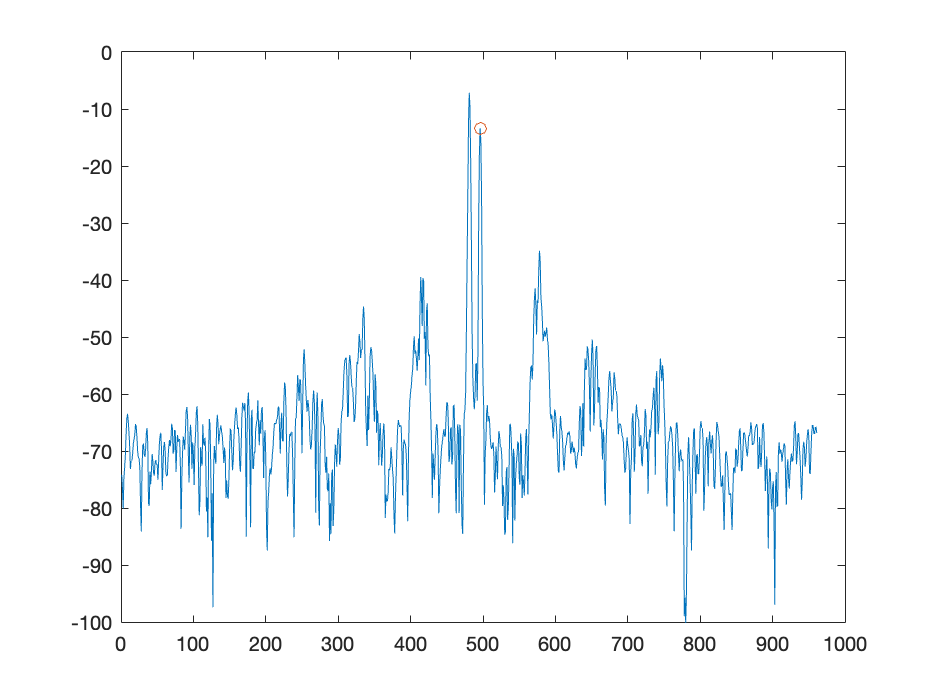

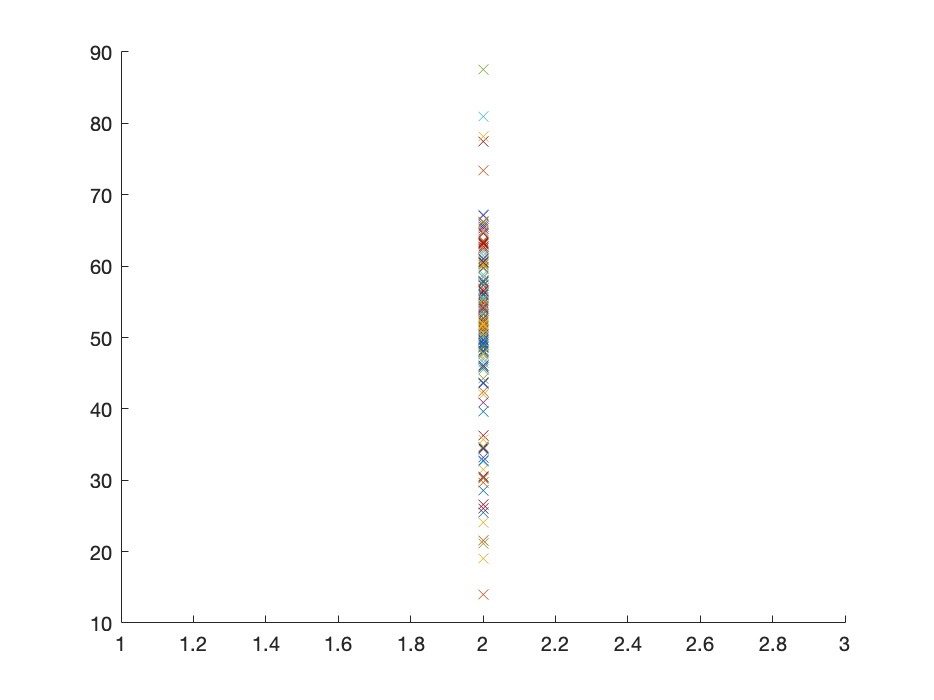

Episode:  17/ 25 | Episode reward:  1573.35 | Episode steps:   30 | Average reward:  1575.13 | Step Count:  510 | Episode Q0:  4120.29


doTraining = true;

if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('/Users/danukatheja/Downloads/IRP/Cranfield Dropoff Service-pS9cskDSAD72goFo/IRP/DQN/E30/Agent29.mat')       
end

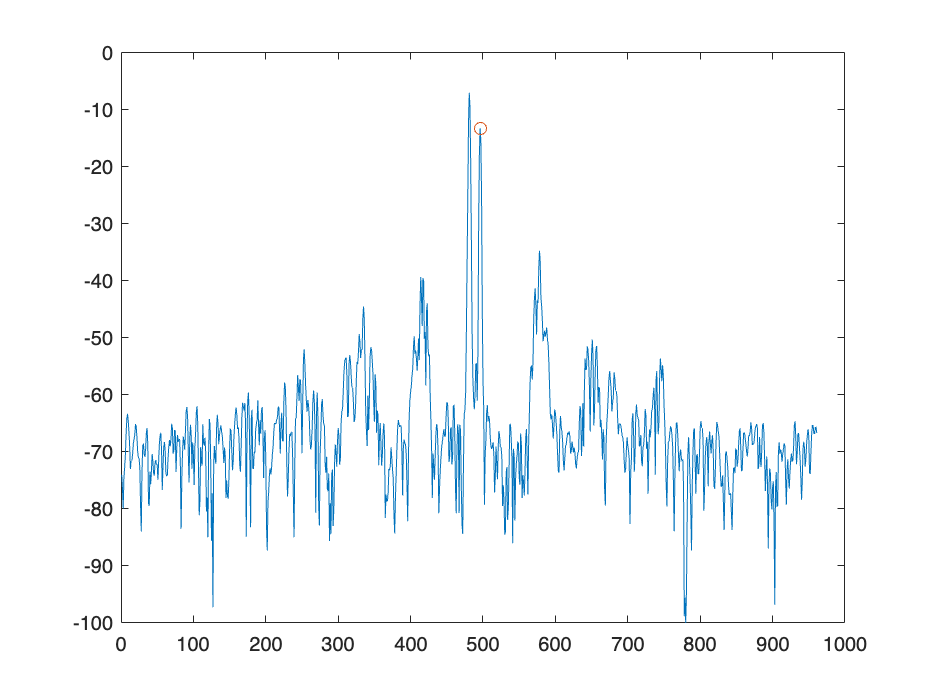

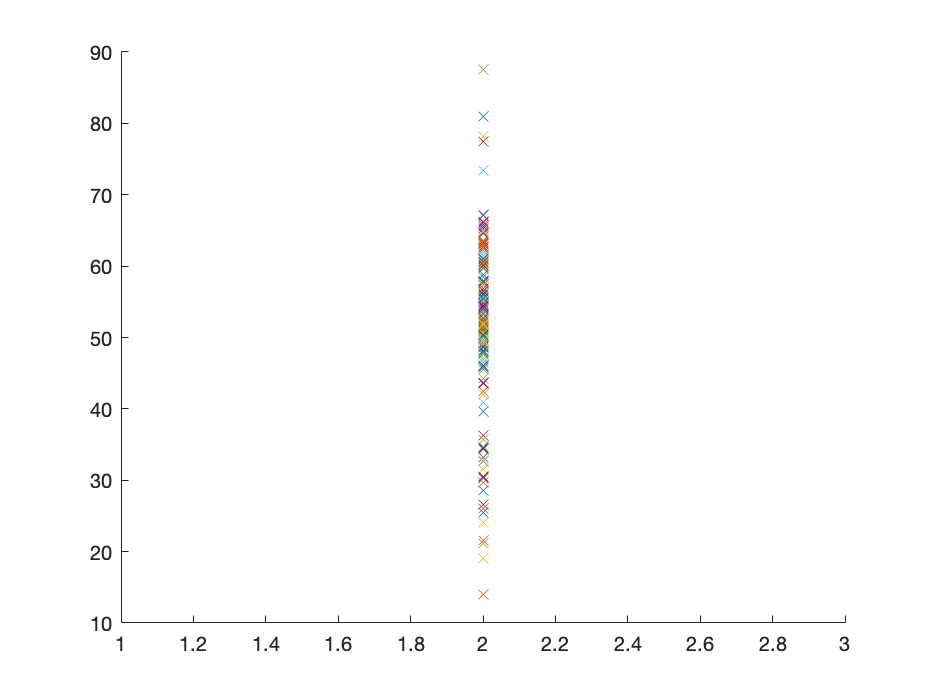

simOptions = rlSimulationOptions('MaxSteps',30);
experience = sim(env,agent,simOptions);

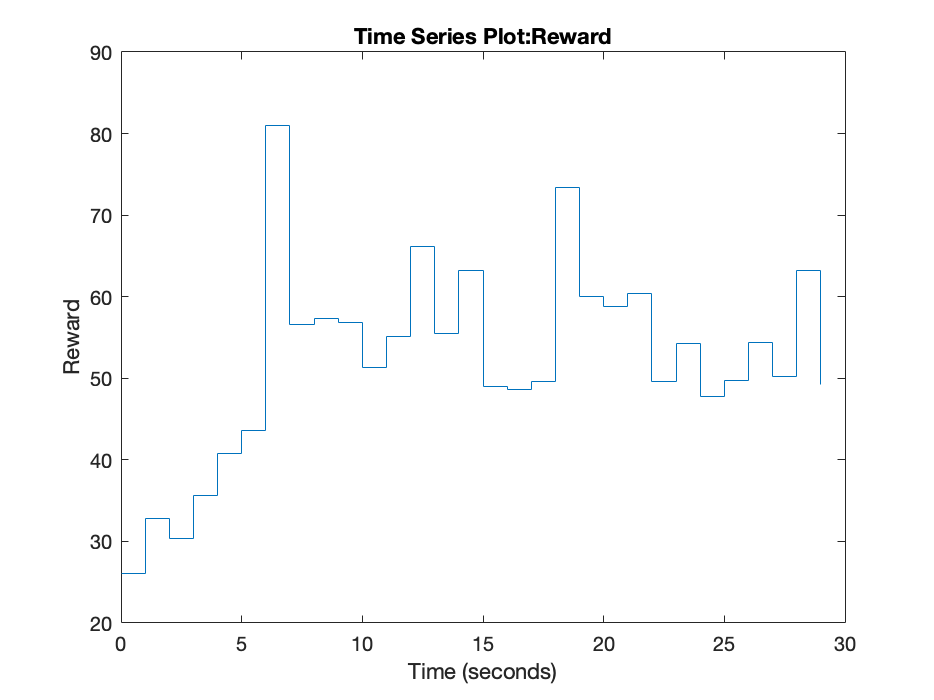

re = experience.Reward;
plot(re)

act = experience.Action;
obs = experience.Observation;

act.BeamformingAction

  timeseries

  Common Properties:
            Name: 'Beamforming Action'
            Time: [30x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x30 double]
        DataInfo: 

obs.BeamformingStates

  timeseries

  Common Properties:
            Name: 'Beamforming States'
            Time: [31x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [3x1x31 double]
        DataInfo: 

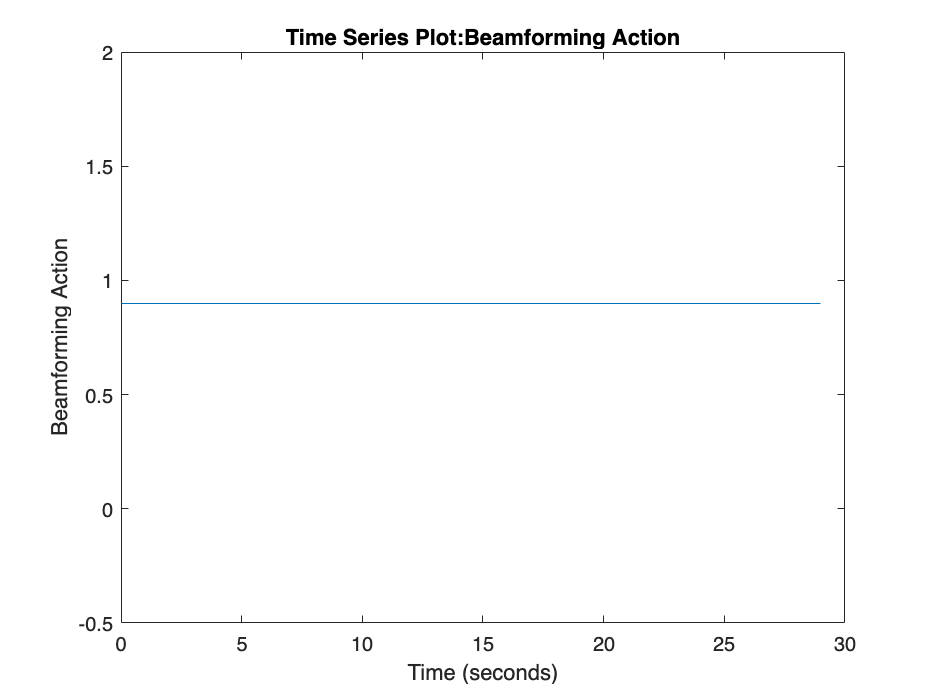

plot(act.BeamformingAction)